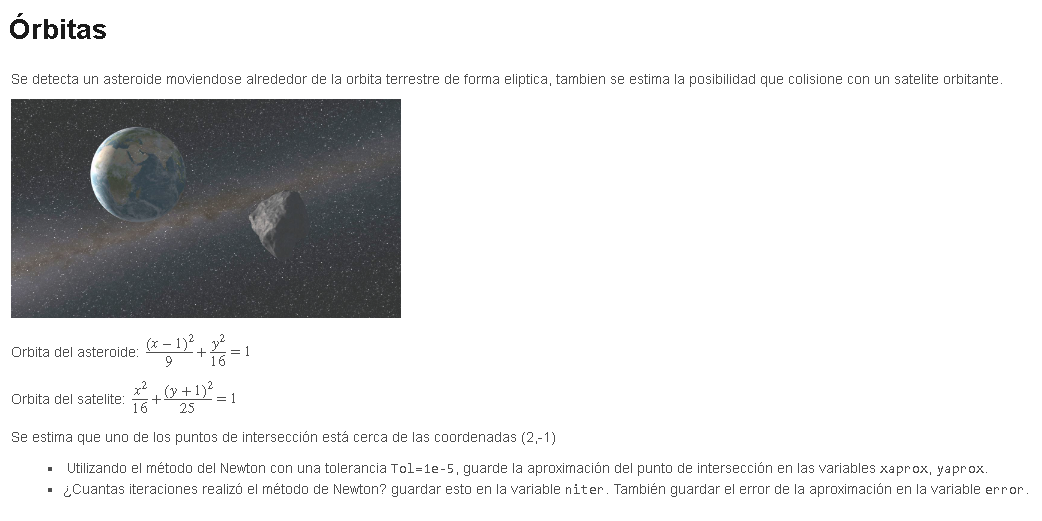

syms x y
F=@ (x,y)([ ((x-1)/3)^2+(y/4)^2-1; (x/4)^2+((y+1)/5)^2-1])

F = function_handle with value:
    @(x,y)([((x-1)/3)^2+(y/4)^2-1;(x/4)^2+((y+1)/5)^2-1])


F(x,y)

$$ans = \left(\begin{array}{c} {\left(\frac{x}{3}-\frac{1}{3}\right)}^{2}+\frac{y^{2}}{16}-1\\ {\left(\frac{y}{5}+\frac{1}{5}\right)}^{2}+\frac{x^{2}}{16}-1 \end{array}\right)$$


tol = 10^(-5)

tol =      9.999999999999999e-06


x0 = [2;-1]

x0 =      2
    -1



hist = newtons(F,x0, tol)

hist =    2.000000000000000  -1.000000000000000   1.000000000000000
   5.000000000000000  -2.277777777777778   0.546011928131609
   4.241018030390290  -0.776686257426518   0.348155775269538
   3.993791305415915  -0.500883549670304   0.068521083124326
   3.978387222301531  -0.480163548853207   0.005170617273165
   3.978315182081817  -0.480071635622606   0.000022937157696
   3.978315180588204  -0.480071633687864   0.000000000482819



[r1 c1] = size(hist);
xaprox = hist(end, 1)

xaprox =    3.978315180588204


yaprox = hist(end,2)

yaprox =   -0.480071633687864


r1 = r1-1;
niter = r1

niter =      6


error = hist(end,3)

error =      4.828192052585904e-10


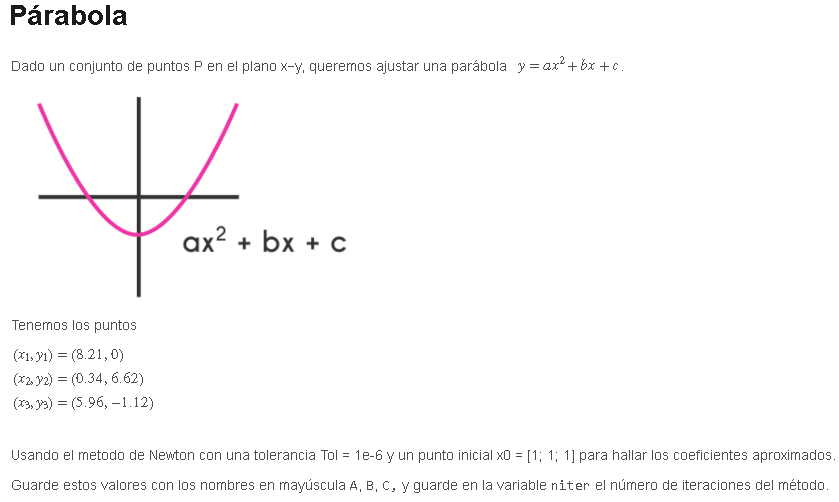

tol = 10^(-6);

X0 = [1;1;1]

X0 =      1
     1
     1



syms a b c 

x1 = 8.21

x1 =    8.210000000000001


y1 = 0

y1 =      0



x2 = 0.34

x2 =    0.340000000000000


y2 = 6.62

y2 =    6.620000000000000



x3 = 5.96

x3 =    5.960000000000000


y3 = -1.12

y3 =   -1.120000000000000




g = @(a,b,c) ([a*x1^2+b*x1+c-y1; a*x2^2+b*x2+c-y2; a*x3^2+b*x3+c-y3])

g = function_handle with value:
    @(a,b,c)([a*x1^2+b*x1+c-y1;a*x2^2+b*x2+c-y2;a*x3^2+b*x3+c-y3])


hist = newton3(g, X0, tol)

$$dF = \left(\begin{array}{ccc} \frac{4743141869425683}{70368744177664} & \frac{821}{100} & 1\\ \frac{289}{2500} & \frac{17}{50} & 1\\ \frac{22201}{625} & \frac{149}{25} & 1 \end{array}\right)$$

hist =    1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000
   0.238246756933423  -2.878178767968816   7.571039456007894   0.810922393490549
   0.238246756933422  -2.878178767968816   7.571039456007894   0.000000000000000



A= hist(end, 1)

A =    0.238246756933422


B = hist(end, 2)

B =   -2.878178767968816


C = hist(end, 3)

C =    7.571039456007894


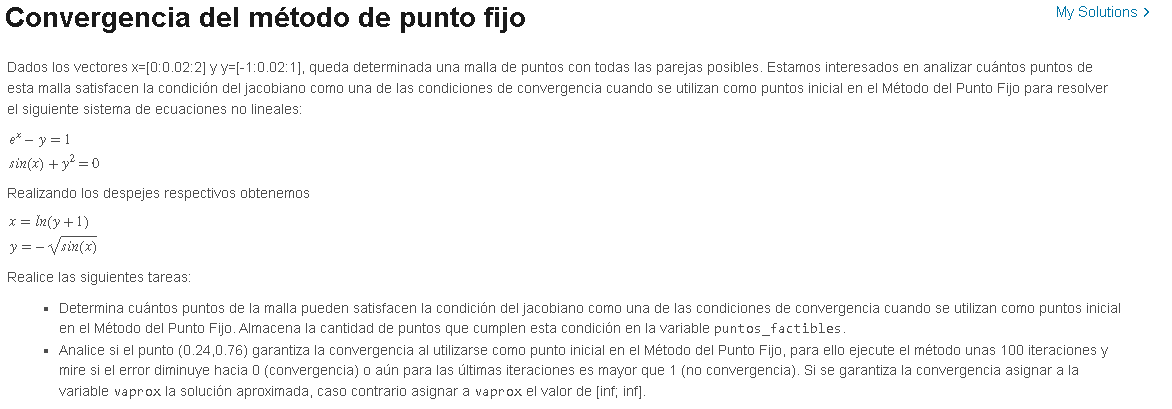


format long
syms a b
%G=@(x,y)[-sqrt(sin(x));log(y+1)]
G= @(a,b) [log(b+1);-sqrt(sin(a))]

G = function_handle with value:
    @(a,b)[log(b+1);-sqrt(sin(a))]



x = 0:0.02:2

x =                    0   0.020000000000000   0.040000000000000   0.060000000000000   0.080000000000000   0.100000000000000   0.120000000000000   0.140000000000000   0.160000000000000   0.180000000000000   0.200000000000000   0.220000000000000   0.240000000000000   0.260000000000000   0.280000000000000   0.300000000000000   0.320000000000000   0.340000000000000   0.360000000000000   0.380000000000000   0.400000000000000   0.420000000000000   0.440000000000000   0.460000000000000   0.480000000000000   0.500000000000000   0.520000000000000   0.540000000000000   0.560000000000000   0.580000000000000   0.600000000000000   0.620000000000000   0.640000000000000   0.660000000000000   0.680000000000000   0.700000000000000   0.720000000000000   0.740000000000000   0.760000000000000   0.780000000000000   0.800000000000000   0.820000000000000   0.840000000000000   0.860000000000000   0.880000000000000   0.900000000000000   0.920000000000000   0.940000000000000   0.960000000000000   0.98000000000

y = -1:0.02:1

y =   -1.000000000000000  -0.980000000000000  -0.960000000000000  -0.940000000000000  -0.920000000000000  -0.900000000000000  -0.880000000000000  -0.860000000000000  -0.840000000000000  -0.820000000000000  -0.800000000000000  -0.780000000000000  -0.760000000000000  -0.740000000000000  -0.720000000000000  -0.700000000000000  -0.680000000000000  -0.660000000000000  -0.640000000000000  -0.620000000000000  -0.600000000000000  -0.580000000000000  -0.560000000000000  -0.540000000000000  -0.520000000000000  -0.500000000000000  -0.480000000000000  -0.460000000000000  -0.440000000000000  -0.420000000000000  -0.400000000000000  -0.380000000000000  -0.360000000000000  -0.340000000000000  -0.320000000000000  -0.300000000000000  -0.280000000000000  -0.260000000000000  -0.240000000000000  -0.220000000000000  -0.200000000000000  -0.180000000000000  -0.160000000000000  -0.140000000000000  -0.120000000000000  -0.100000000000000  -0.080000000000000  -0.060000000000000  -0.040000000000000  -0.02000000000


[r1 c1] = size(x)

r1 =      1


c1 =    101



%tmp2 = [];
puntos_factibles = 0;

dG=jacobian(G(a,b),[a,b]);
dGfun=matlabFunction(dG);
%z = norm(dGfun(x0(i),x0(o)),inf);

for i = 1:c1
    for j = 1:c1
        tmp = dGfun(x(i),y(j));
        %val = max( abs(tmp(1,1)) + abs(tmp(1,2)) ,abs(tmp(2,1)) + abs(tmp(2,2))  );
        val = norm(dGfun(x(i),y(j)),inf);
        if(val<1)
            %tmp2=[tmp2; x(i) y(j) val];
            puntos_factibles = puntos_factibles+1;
        end
    end 
end
%tmp2
puntos_factibles

puntos_factibles =         4450




x0 = [0.24; 0.76]

x0 =    0.240000000000000
   0.760000000000000


n = 100

n =    100


hist = pfijos_it(G, x0,100)

$$ans = \left(\begin{array}{c} \log\left(q+1\right)\\ -\sqrt{\sin\left(p\right)} \end{array}\right)$$

hist =   0.565313809050060 + 0.000000000000000i -0.487547563246023 + 0.000000000000000i  1.000000000000000 + 0.000000000000000i
  0.565313809050060 + 0.000000000000000i -0.487547563246023 + 0.000000000000000i  1.671165556861604 + 0.000000000000000i
 -0.668547378610051 + 0.000000000000000i -0.731902199197672 + 0.000000000000000i  1.244714857469763 + 0.000000000000000i
 -1.316403436674545 + 0.000000000000000i  0.000000000000000 + 0.787303458740852i  0.700810989115922 + 0.000000000000000i
  0.241165768725514 + 0.666951059237974i  0.000000000000000 + 0.983776528499750i  1.397101535890321 + 0.000000000000000i
  0.338462214723813 + 0.777220271582725i -0.724626654836233 - 0.480760614349418i  1.345485311358868 + 0.000000000000000i
 -0.590516884442983 - 1.050626898529422i -0.823819824962510 - 0.491125264286032i  1.331183359100306 + 0.000000000000000i
 -0.650529234308730 - 1.226367641348883i -0.489605313706272 + 1.064485143800983i  0.875874809555984 + 0.000000000000000i
  0.165956413851211 + 1.1

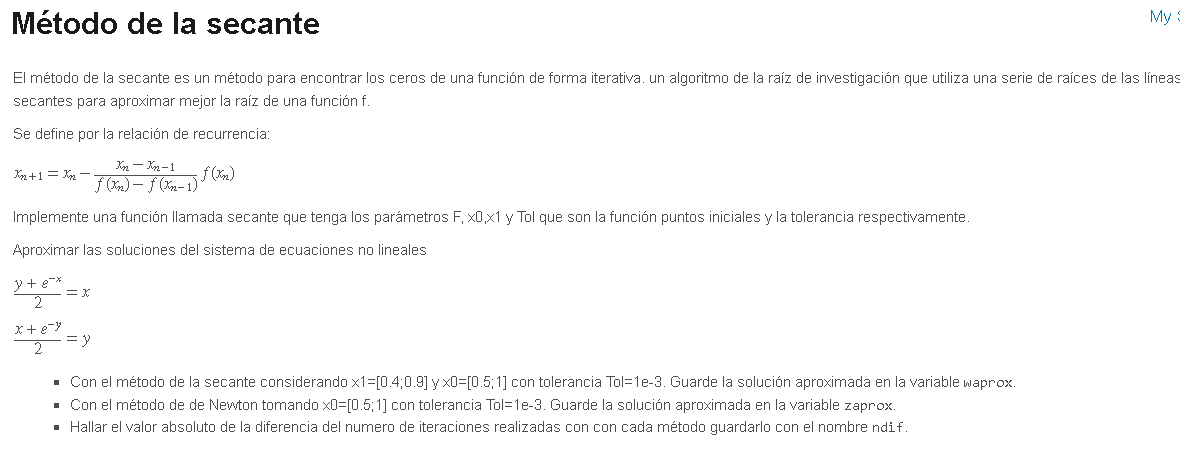

syms x y
tol = 10^(-3)

tol =      1.000000000000000e-03



%Metodo secante
x1 = [0.4 ; 0.9]

x1 =    0.400000000000000
   0.900000000000000


x0 = [0.5 ; 1]

x0 =    0.500000000000000
   1.000000000000000



G = @(x,y) ([ (y+exp(-x))/2-x;(x+exp(-y))/2-y])

G = function_handle with value:
    @(x,y)([(y+exp(-x))/2-x;(x+exp(-y))/2-y])



hist1 = secante(G, x0, x1, tol)

hist1 =    0.500000000000000   1.000000000000000   1.000000000000000
   0.400000000000000   0.900000000000000   1.000000000000000
   0.559589366108391   0.550659763458461   0.444968348766295
   0.567226755823898   0.567741719885100   0.021284760309059
   0.567143874115867   0.567144610871042   0.000744466400808



[r1 c1] = size(hist1);

waprox = hist1(end, 1:2)

waprox =    0.567143874115867   0.567144610871042


r1 = r1-2;

%Metodo newton
x0 = [0.5; 1]

x0 =    0.500000000000000
   1.000000000000000



hist2 = newtons(G, x0, tol)

hist2 =    0.500000000000000   1.000000000000000   1.000000000000000
   0.558792312274331   0.546713304785810   0.579830550678777
   0.567112883732123   0.567084973897118   0.025401115460478
   0.567143290116870   0.567143289920014   0.000072707648961



[r2 c2] = size(hist2);

r2 = r2-1;
zaprox = hist2(end, 1:2)

zaprox =    0.567143290116870   0.567143289920014



ndif = abs(r2-r1)

ndif =      0


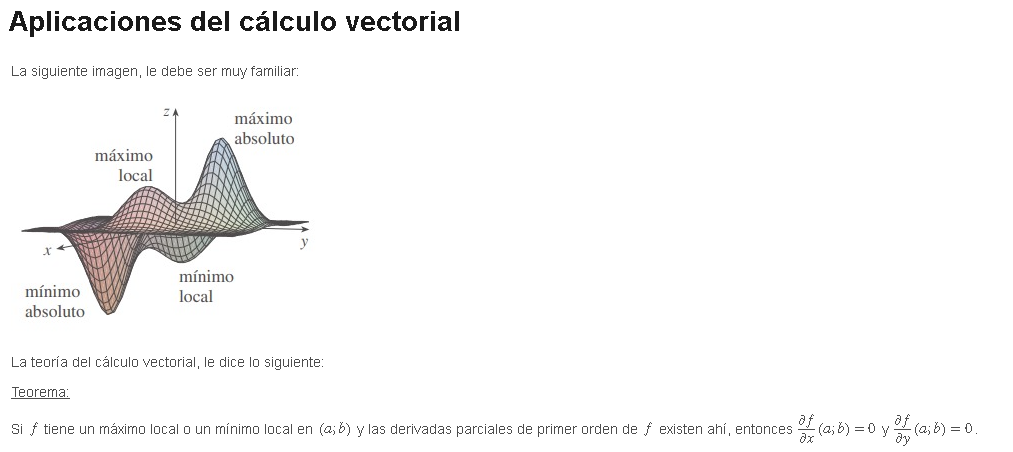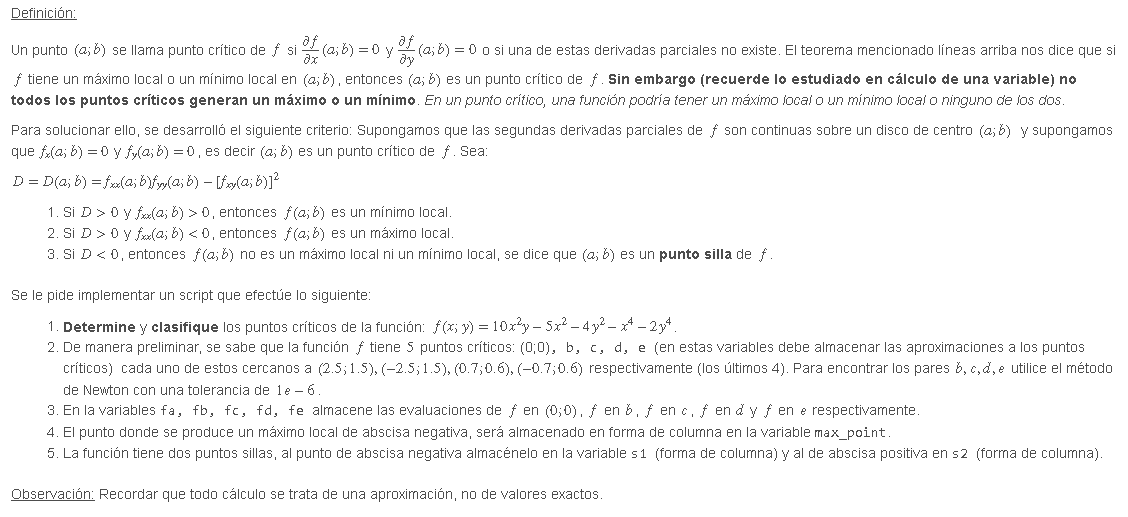

syms x y
f = 10*(x^2)*y-5*(x^2)-4*(y^2)-x^4-2*y^4

$$f = -x^{4}+10\,x^{2}\,y-5\,x^{2}-2\,y^{4}-4\,y^{2}$$


dp = @ (x,y) [diff(f,x);diff(f,y)]

dp = function_handle with value:
    @(x,y)[diff(f,x);diff(f,y)]


p1 = [2.5 ; 1.5]

p1 =    2.500000000000000
   1.500000000000000


p2 = [-2.5 ; 1.5]

p2 =   -2.500000000000000
   1.500000000000000


p3 = [0.7 ; 0.6]

p3 =    0.700000000000000
   0.600000000000000


p4 = [-0.7 ; 0.6]

p4 =   -0.700000000000000
   0.600000000000000


tol = 10^(-6);

% PARA B
hist = newtons(dp, p1, tol)

hist =    2.500000000000000   1.500000000000000   1.000000000000000
   2.939560439560440   2.233516483516484   0.198686399580839
   2.721088959686958   1.971713963360175   0.077909201264980
   2.650242486821464   1.903514945523411   0.021712081361893
   2.644261925852960   1.898414270142103   0.001837252900052
   2.644224302922355   1.898384432408285   0.000011558089156
   2.644224301508298   1.898384431337409   0.000000000434410


b = hist(end, 1:2)'

b =    2.644224301508298
   1.898384431337409



%PARA C
hist = newtons(dp, p2, tol)

hist =   -2.500000000000000   1.500000000000000   1.000000000000000
  -2.939560439560440   2.233516483516484   0.198686399580839
  -2.721088959686958   1.971713963360175   0.077909201264980
  -2.650242486821464   1.903514945523411   0.021712081361893
  -2.644261925852960   1.898414270142103   0.001837252900052
  -2.644224302922355   1.898384432408285   0.000011558089156
  -2.644224301508298   1.898384431337409   0.000000000434410


c = hist(end, 1:2)'

c =   -2.644224301508298
   1.898384431337409




%PARA D
hist = newtons(dp, p3, tol)

hist =    0.700000000000000   0.600000000000000   1.000000000000000
   0.869861713005794   0.645075960461606   0.156850815340224
   0.856599071172868   0.646621831213456   0.012357371140719
   0.856656855859372   0.646772201877881   0.000140088939561
   0.856656871446373   0.646772199079257   0.000000014521226


d = hist(end, 1:2)'

d =    0.856656871446373
   0.646772199079257




%PARA E
hist = newtons(dp, p4, tol)

hist =   -0.700000000000000   0.600000000000000   1.000000000000000
  -0.869861713005794   0.645075960461606   0.156850815340224
  -0.856599071172868   0.646621831213456   0.012357371140719
  -0.856656855859372   0.646772201877881   0.000140088939561
  -0.856656871446373   0.646772199079257   0.000000014521226


e = hist(end, 1:2)'

e =   -0.856656871446373
   0.646772199079257



f(x,y) = matlabFunction(f)

$$f(x, y) = -x^{4}+10\,x^{2}\,y-5\,x^{2}-2\,y^{4}-4\,y^{2}$$

fa = double(f(0,0))

fa =      0


fb = double(f(b(1),b(2)))

fb =    8.495858128438295


fc = double(f(c(1),c(2)))

fc =    8.495858128438295


fd = double(f(d(1),d(2)))

fd =   -1.484678818966982


fe = double(f(e(1),e(2)))

fe =   -1.484678818966982



f = f(x,y)

$$f = -x^{4}+10\,x^{2}\,y-5\,x^{2}-2\,y^{4}-4\,y^{2}$$

D = diff(diff(f,x),x)*diff(diff(f,y),y)-(diff(diff(f,x),y))^2

$$D = \left(24\,y^{2}+8\right)\,\left(12\,x^{2}-20\,y+10\right)-400\,x^{2}$$

D = matlabFunction(D)

vb = D(b(1),b(2))

vb =      2.488717233704449e+03


v2b = double(subs(diff(diff(f,x),x), {x,y},{b(1),b(2)}))

v2b =  -55.935377253496362



vc= D(c(1),c(2))

vc =      2.488717233704449e+03


v2c = double(subs(diff(diff(f,x),x), {x,y},{c(1),c(2)}))

v2c =  -55.935377253496362



vd= D(d(1),d(2))

vd =     -1.876362642945676e+02


v2d = double(subs(diff(diff(f,x),x), {x,y},{d(1),d(2)}))

v2d =   -5.870887963170304



de= D(e(1),e(2))

de =     -1.876362642945676e+02


v2e = double(subs(diff(diff(f,x),x), {x,y},{e(1),e(2)}))

v2e =   -5.870887963170304



max_point = c

max_point =   -2.644224301508298
   1.898384431337409


s1 = e

s1 =   -0.856656871446373
   0.646772199079257


s2 = d

s2 =    0.856656871446373
   0.646772199079257


function z=newtons(F,x0,Tol)
syms x y
F = matlabFunction(F(x,y));
dF = jacobian(F(x,y),[x,y]);
df_fun=matlabFunction(dF);

error=1;
z=[x0' error];
while error>Tol
    x1=x0-inv(df_fun(x0(1),x0(2)))*F(x0(1),x0(2));
    error=norm(x1-x0,"inf")/norm(x1);
    z=[z;x1' error];
    x0=x1;
end
end

function val=newton3(F,x0,Tol)
syms a b c
dF = jacobian(F(a,b,c),[a,b,c])
df_fun=double(dF);
error=1;
val=[x0' error];

while error>Tol
    x1=x0-inv(df_fun)*F(x0(1),x0(2),x0(3));
    error=norm(x1-x0,"inf")/norm(x1);
    val=[val;x1' error];
    x0=x1;
end

end


function z = check_convergencia_pf(G, x0)
syms x y
dG=jacobian(G(x,y),[x,y]);
dGfun=matlabFunction(dG);
dGfun(x0(1),x0(2));
z = norm(dGfun(x0(1),x0(2)),inf);
end

function z=pfijos_it(g,x0,it)
error=1;
z=[g(x0(1),x0(2))' error];
syms p q
g(p,q)
for i = 1:it
    x1=g(x0(1),x0(2));
    error=norm(x1-x0,inf)/norm(x1);
    z=[z;x1' error];
    x0=x1;
end
end

function z=pfijos(g,x0,Tol)
error=1;
z=[g(x0(1),x0(2))' error];
while error>Tol
x1=g(x0(1),x0(2));
error=norm(x1-x0,inf)/norm(x1);
z=[z;x1' error];
x0=x1;
end
end

function z = secante(g, X0, X1,Tol)
error = 1;
z = [X0' error; X1' error];
while error>Tol
    x0 = X0(1);
    y0 = X0(2);

    x1= X1(1);
    y1= X1(2);

    fx = (g(x1,y0)-g(x0,y0))/(x1-x0);
    fy = (g(x0,y1)-g(x0,y0))/(y1-y0);

    M = [ fx fy];
    X2= X1 -inv(M)*g(x1,y1);
    error = norm(X2-X1,inf)/norm(X2);
    z = [z; X2' error];
    X0 = X1;
    X1=X2;
end
end
